# Principal component analysis

#### Background 

- **PCA** is a dimensionality reduction technique used to simplify complex datasets.

- It transforms the original variables into new, uncorrelated variables called **principal components**.

- The first principal component captures the **maximum variance** in the data.

- Each subsequent component captures the **next highest variance**, orthogonal to the previous ones.

- PCA helps in visualizing high-dimensional data in **2D or 3D plots**.

- It is often used to **remove noise** and **reduce redundancy** in data.

- The transformation is achieved via **eigenvalue decomposition** of the covariance (correlation) matrix.

- The eigenvectors become the **principal axes** (directions of maximum variance).

- Eigenvalues indicate how much **variance** each component explains.

- PCA is widely used in **data preprocessing**, **compression**, and **feature extraction**.

#### Example: the citiesItaly dataset

load citiesItaly.mat
disp(citiesItaly.Properties.Description)

The citiesItaly dataset contains 107 records for the 107 provinces of Italy for seven indicators concerning the quality of life: The 7 variables are:
addedval = added value per capita
depost = amount of bank deposits per inhabitant
unemploy = unemployment rate
export = percentage of export divided by GNP of the province
bankrup = percentage of bankruptcy declarations on active companies
billsover = bills overdue indicator (percentage of bills protested on bills issued)
The data come from the Italian financial newspaper Il Sole 24 Ore, which every year produces the quality of life ranking of the Italian provinces.


The routine which implements PCA is called [pcaFS](http://rosa.unipr.it/FSDA/pcaFS.html).

Initial correlation matrix
                  addedval    depos    pensions    unemploy    export    bankrup    billsoverd
                  ________    _____    ________    ________    ______    _______    __________

    addedval        1.00       0.89      0.74       -0.80       0.56      0.06        -0.37   
    depos           0.89       1.00      0.73       -0.69       0.44      0.17        -0.24   
    pensions        0.74       0.73      1.00       -0.50       0.31      0.35        -0.29   
    unemploy       -0.80      -0.69     -0.50        1.00      -0.61      0.15         0.40   
    export          0.56       0.44      0.31       -0.61       1.00      0.04 

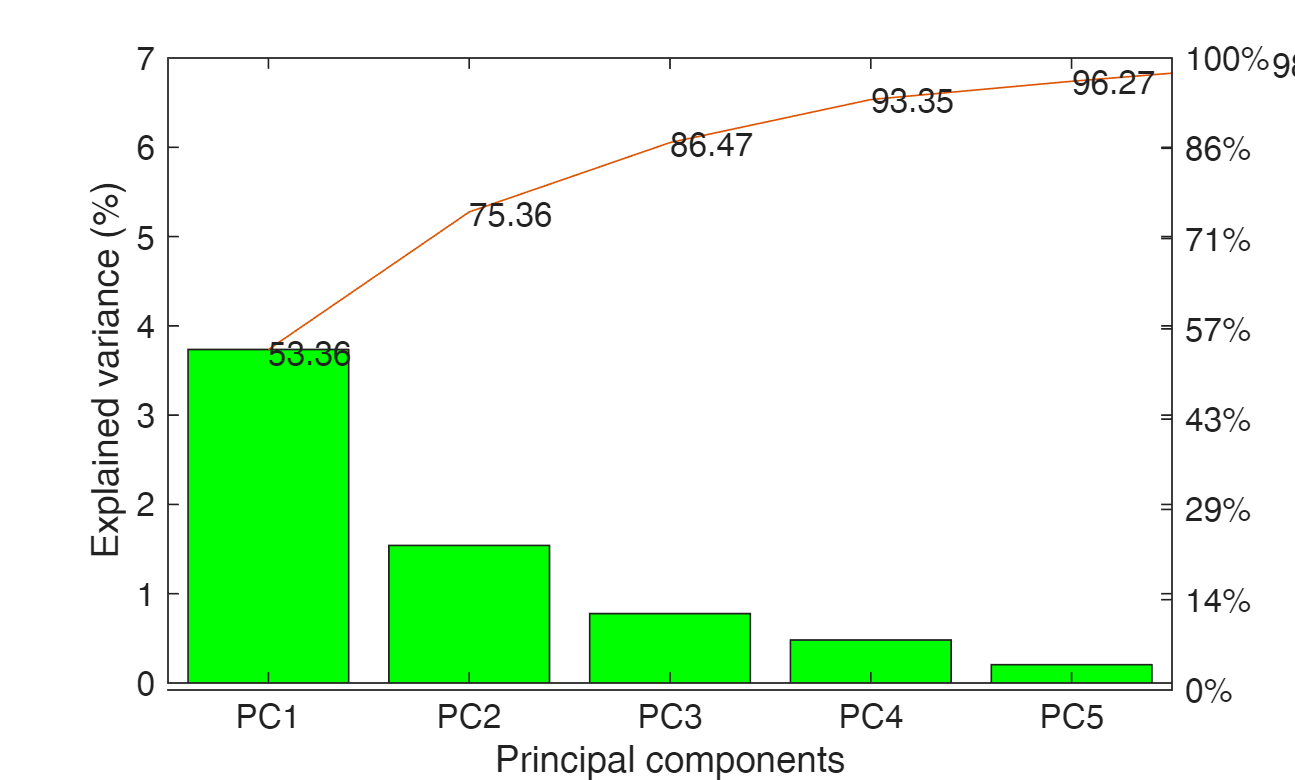

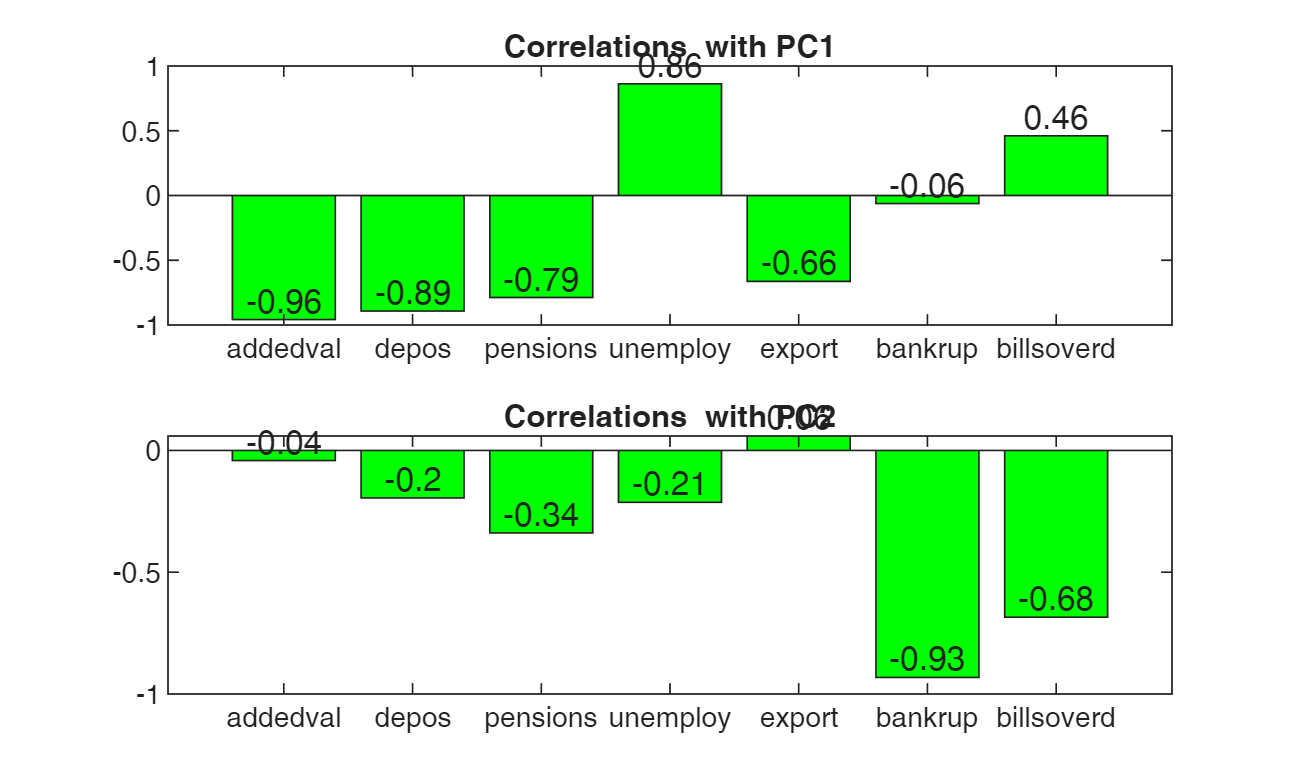

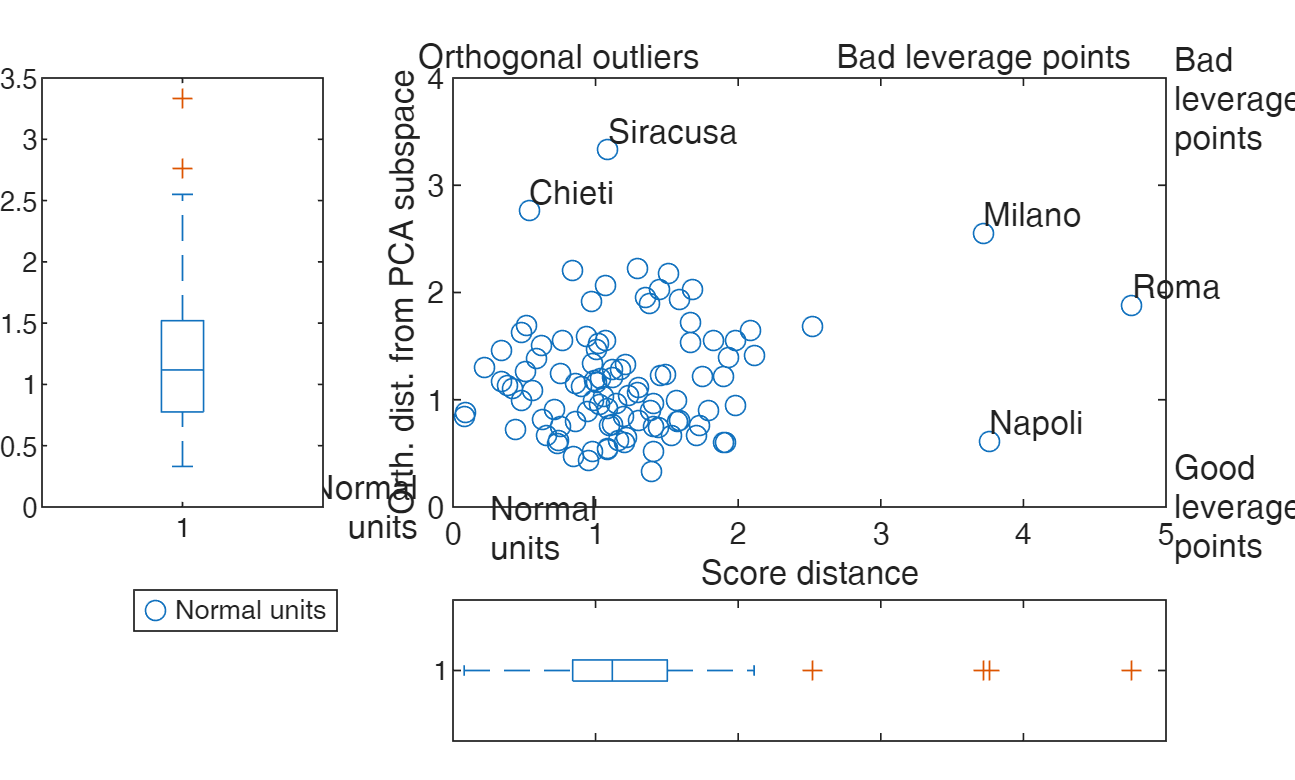

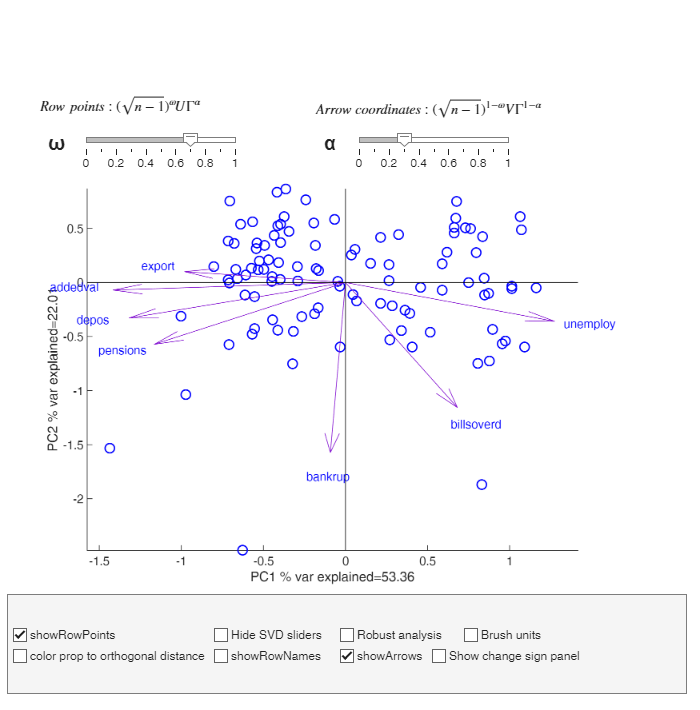

out = struct with fields:
            Rtable: [7×7 table]
         explained: [7×3 double]
        explainedT: [7×3 table]
             coeff: [7×2 double]
            coeffT: [7×2 table]
          loadings: [7×2 double]
         loadingsT: [7×2 table]
     communalities: [7×3 double]
    communalitiesT: [7×3 table]
             score: [103×2 double]
            scoreT: [103×2 table]
          orthDist: [103×1 double]
         scoreDist: [103×1 double]
             class: 'pcaFS'


out=pcaFS(citiesItaly)

VARIANCE EXPLAINED

Replacing the 7 original variables with the first two principal components results in an information loss of just under 25 percent. 

INTERPRETATION OF THE PCs

The first principal component is strongly and inversely correlated with the variables va, deposits, pensions, and export, and is positively correlated with the unemployment rate (unemploy) and, to a lesser extent, with protests (billsover). This latent variable can be interpreted as an overall indicator of the poverty level of the province. In other words, the higher the score on the first principal component (Y1), the poorer the province.

Remark: Eigenvectors are defined up to sign, so if the elements of v1 (first eigenvector) are reversed in sign, the first principal component should be interpreted as an index of wealth.

The second principal component (Y2) is strongly and directly correlated with the variables failures (bankrup) and protests (billsover). This component should therefore be interpreted as an indicator of "business distress." The higher the value of Y2, the higher the index of business distress in that particular province.

The correlations between the original variables and the principal components (loadings matrix) can be visualized using bar charts.

THE COMMUNALITIES

The sum of the squares of each row of the loadings matrix is the so called communality (communality), that is, the portion of the variance of each variable explained by the first k components (if we have decided to retain k components).

The variable best explained is va, followed by bankrup. The least explained variable is export.  The numbers in the component matrix are represented using arrows in the biplot.

THE OUTLIER MAP plot

The graph that plots the "score distance" (SD) on the horizontal axis and the "orthogonal distance" (OD) on the vertical axis for each point is not as the "outlier map."

We can distinguish four types of observations. The so-called "regular observations" form a homogeneous group that is close to the subspace formed by the first two principal components. These observations have low values of SDi and ODi

The "good leverage points" are those that are very close to the subspace but far from the regular observations.  These points have high SDi values but low ODi values. 

 "bad leverage points" are the observations which are far from the cloud of points representing the "regular observations" and, at the same time, have a high distance from the subspace. These points have high values of both SDi and ODi

Finally, there is the case of observations that are "orthogonal outliers," i.e., points that have a very large orthogonal distance but cannot be identified in the reduced subspace because they are very close to the other points in the subspace. Thise observation have low SDi values but very high ODi values.

For the description and an example of the buttons inside the biplotAPP Gui see file [ExamplesPCAinteractive.mlx](matlab:open('ExamplesPCAinteractive.mlx')) in this folder.

For a detaild description of all the input and output arguments of routine pcaFS see the corresponding HTML help  file [pcaFS](http://rosa.unipr.it/FSDA/pcaFS.html).